% Problem 1(a) - Test
clc;
clear all;
close all;

x = 20/sqrt(2);
y = 20/sqrt(2);
[T1, T2] = getJointAngles(x,y);
disp('The value of theta1 : ')

The value of theta1 : 


disp(T1)

   0.785398150492664



disp('The value of theta2 : ')

The value of theta2 : 


disp(T2)

     2.580956827951785e-08



% Problem 1(b) - Test
x = 20/sqrt(2);
y = 20/sqrt(2);
[T1, T2] = getOptimizer(x,y);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


disp('The value of theta1 : ')

The value of theta1 : 


disp(T1)

   0.785398152194258



disp('The value of theta2 : ')

The value of theta2 : 


disp(T2)

     2.240638097283920e-08



% Problem 1(c) - Test
x = 20/sqrt(2);
y = 20/sqrt(2);
final_result = bruteForceSearch(x,y);
disp('The value of theta1 & theta2 : ')

The value of theta1 & theta2 : 


disp(final_result(1,:))

   0.789344887836631  -0.007893448878366



disp('The value of theta1 & theta2 : ')

The value of theta1 & theta2 : 


disp(final_result(2,:))

   0.781451438958265   0.007893448878366



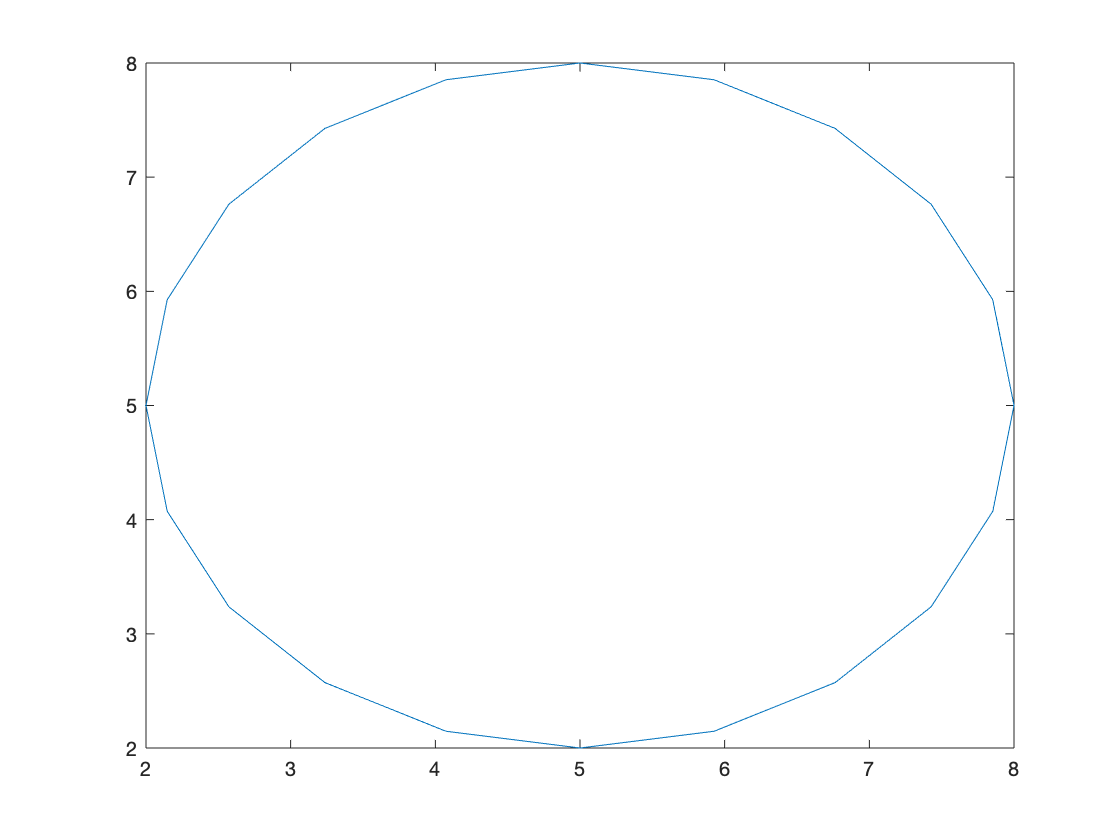

% Problem 1(d) - Test
clear;
clc;
close all

% Circle Trajectory to follow
circleCenter = [5 5]; % Center of the circle
radius = 3; % Radius of the circle
% Link Lengths
a1 = 10;
a2 = 10;
xc = circleCenter(1);
yc = circleCenter(2);

r = sqrt(xc^2+yc^2);

max_r = r + radius;
if max_r > (a1+a2)
    disp('The points on the circle are not reachable\n');
end
alpha = 0:2*pi/20:2*pi;
x = xc + radius*cos(alpha);
y = yc + radius*sin(alpha);

points = [x' y'];
plot(x,y)

% Problem 1(e) - Test
% Plot robot configuration when given theta1 and theta2

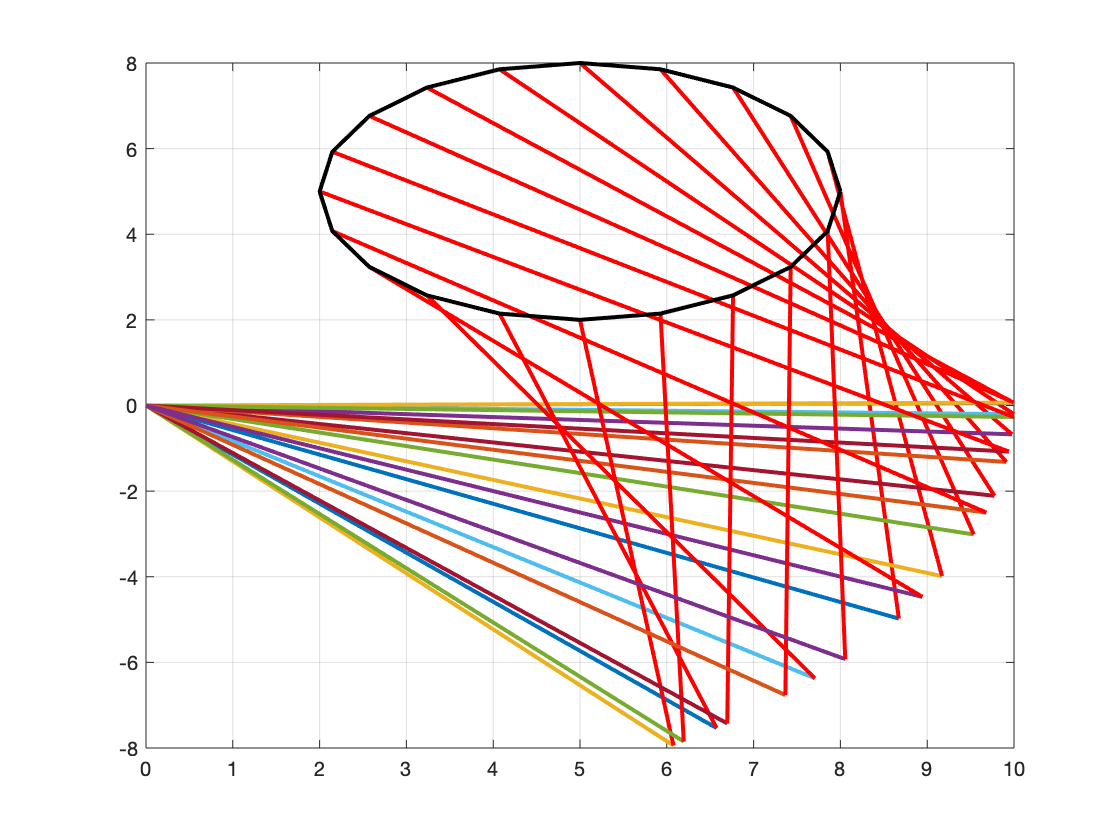

% Problem 1(f) - Test

tic

a1 = 10; % given value of link 1
a2 = 10; % given value of link 2

for i = 1:20
    x(i) = points(i,1); % x coordinate of the end position
    y(i) = points(i,2); % y coordinate of the end position
    [t1, t2] = getJointAngles(x(i),y(i)); % Obtain theta1 and theta2
    [link1x(i,:), link1y(i,:), link2x(i,:), link2y(i,:)] = getPlots(t1, t2);
    plot(link1x(i,:),link1y(i,:),'linewidth',2);
    hold on;
    plot(link2x(i,:),link2y(i,:),'r','linewidth',2)
    
end
plot(x,y,'k','linewidth',2);grid

toc

Elapsed time is 0.222152 seconds.


% Problem 1(g) - Test
% Using Optimization
tic

a1 = 10;
a2 = 10;

for i = 1:20
    x(i) = points(i,1);
    y(i) = points(i,2);
    [t1, t2] = getOptimizer(x(i), y(i));
    [link1x(i,:), link1y(i,:), link2x(i,:), link2y(i,:)] = getPlots(t1, t2);
    plot(link1x(i,:), link1y(i,:), 'LineWidth', 2);
    hold on;
    plot(link2x(i,:), link2y(i,:), 'r','LineWidth',2);
end


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


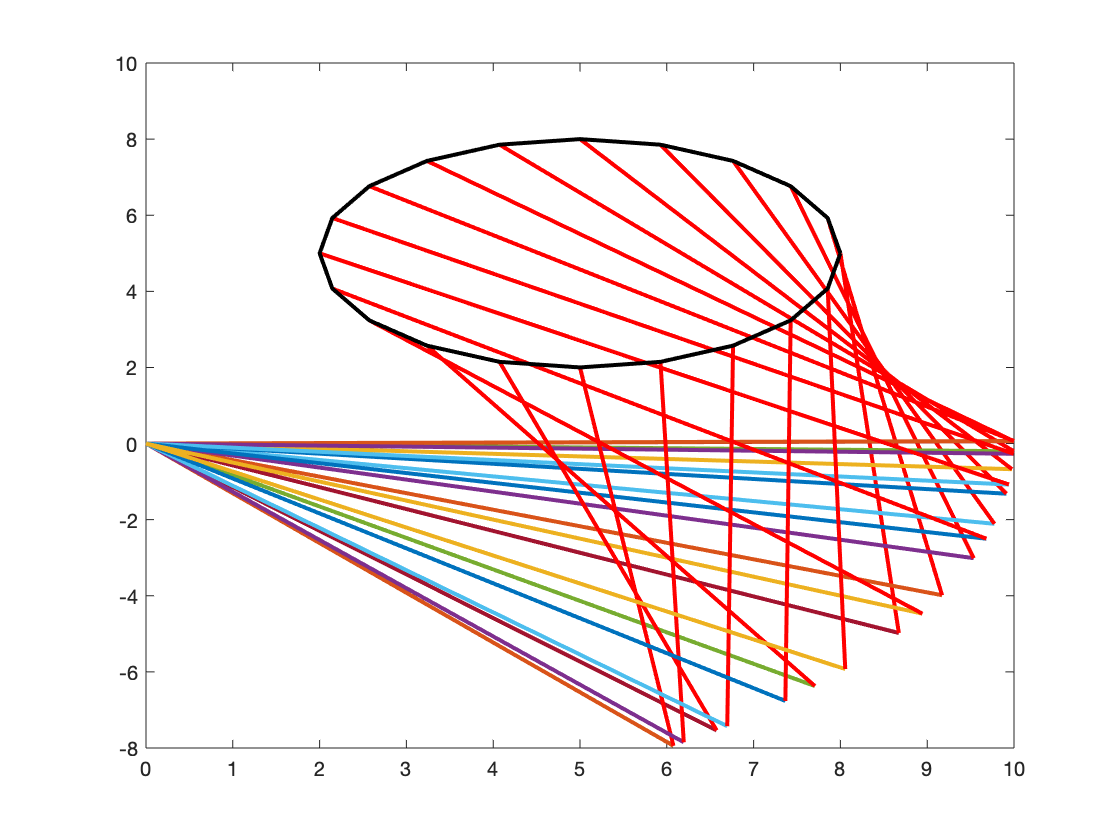


plot(x,y, 'k', 'LineWidth',2);grid

toc

Elapsed time is 0.428273 seconds.


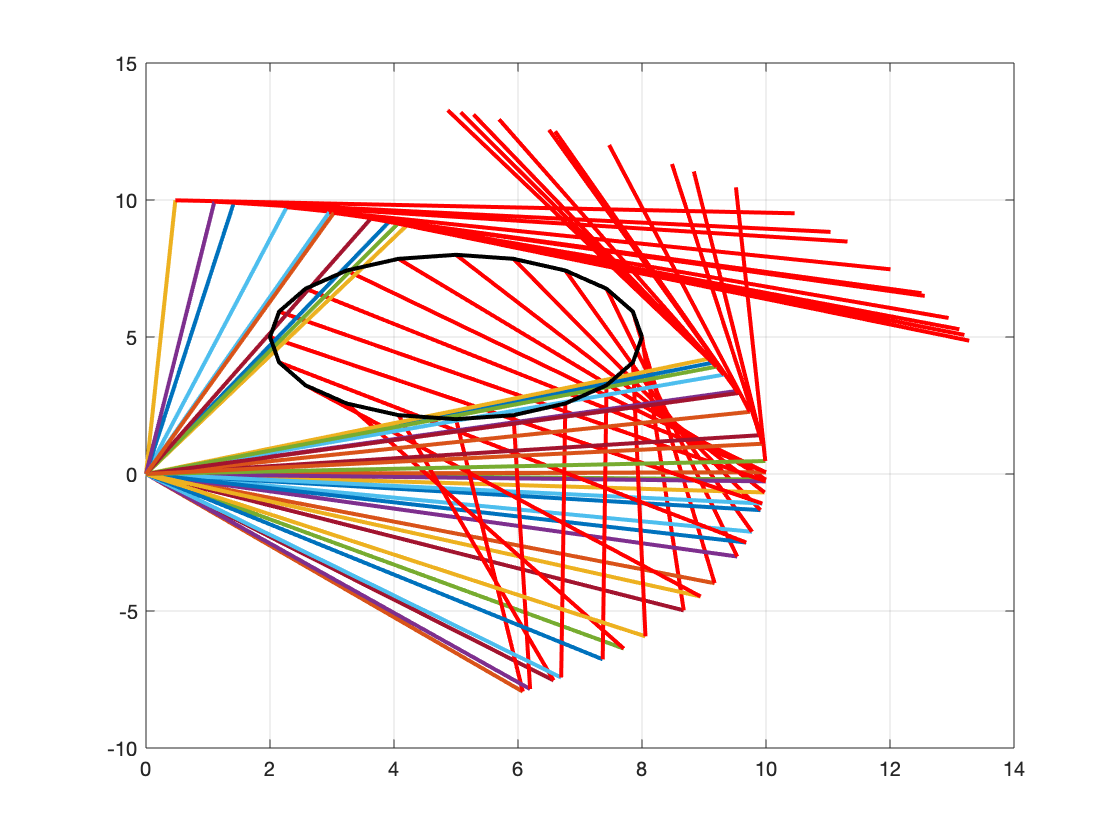

% Problem 1(g) - Test
% Using BruteForceSearch
tic

a1 = 10; % given value of link 1
a2 = 10; % given value of link 2

for i = 1:20
    x(i) = points(i,1); % x coordinate of the end position
    y(i) = points(i,2); % y coordinate of the end position
    result = bruteForceSearch(x(i),y(i)); % Obtain theta1 and theta2
    t1 = result(1);
    t2 = result(2);
    [link1x(i,:), link1y(i,:), link2x(i,:), link2y(i,:)] = getPlots(t1, t2);
    plot(link1x(i,:),link1y(i,:),'linewidth',2);
    hold on;
    plot(link2x(i,:),link2y(i,:),'r','linewidth',2)
    
end
plot(x,y,'k','linewidth',2);grid

toc

Elapsed time is 0.691731 seconds.


% Problem 2 - Test
clc;
clear ALL;
close ALL;
x = 20/sqrt(2);
y = 20/sqrt(2);
% Define initial values
theta1_init = 0.4;

% Define function handle
fun2 = @inverseEqn2;

% Compute inversse using optimization
[z, fval] = fmincon(fun2, theta1_init, [], []);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


theta1 = z;
theta2 = acos((x - a1*cos(theta1))/a2) - theta1;

% Print values
disp('The value of theta1 : ')

The value of theta1 : 


disp(theta1);

   0.785398160463945



disp('The value of theta2 : ')

The value of theta2 : 


disp(theta2);

     5.867006214188564e-09



% Problem 1(a)

function [theta1, theta2] = getJointAngles(x,y)
a1 = 10;
a2 = 10;

theta2 = acos((x^2 + y^2 - a1^2 - a2^2)/(2*a1*a2));
if theta2 >= 0
    theta1 = atan(y/x) - atan(a2*sin(theta2)/(a1 + a2*cos(theta2)));
else
    theta1 = atan(y/x) + atan(a2*sin(theta2)/(a1 + a2*cos(theta2)));
end

end

% Problem 1(b)

function [theta1, theta2] = getOptimizer(x,y)

a1 = 10;
a2 = 10;

theta_init = 0.4;

f = @(theta1)getF(theta1, x, y, a1, a2);

[z, ~, exitflag] = fminunc(f, theta_init);
%if exitflag ~= 1
%    disp("Value not optimized")
%else

theta1 = z;
theta2 = acos((x - a1*cos(theta1))/a2) - theta1;
%end

end

function f = getF(theta1, x, y, a1, a2)
f = abs(a1*sin(theta1) + a2*sin(acos((x - a1*cos(theta1))/a2)) - y);
end

% Problem 1(c)
function result = bruteForceSearch(x, y)
a1 = 10;
a2 = 10;

theta1 = linspace(0, pi/2, 200);
theta2 = linspace(-pi/2, pi/2, 200);

for i = 1:length(theta1)
    for j = 1:length(theta2)
        newX = a1*cos(theta1(i)) + a2*cos(theta1(i)+theta2(j));
        newY = a1*sin(theta1(i)) + a2*sin(theta1(i)+theta2(j));
        error(i,j) = (x - newX)^2 + (y - newY)^2;
    end
end

M = min(error);
minError = min(M);

[row, col] = find(error == minError);

final_theta1 = theta1(row);
final_theta2 = theta2(col);

result = [final_theta1', final_theta2'];
end

% Problem 1(e)
function [link1x,link1y,link2x,link2y] = getPlots(theta1, theta2)
a1 = 10;
a2 = 10;
link1x = [0:0.2:a1]*cos(theta1);
link1y = [0:0.2:a1]*sin(theta1);
link2x = [0:0.2:a2]*cos(theta1+theta2)+a1*cos(theta1);
link2y = [0:0.2:a2]*sin(theta1+theta2)+a1*sin(theta1);
end

% Problem 2
function f = inverseEqn2(theta1)
x = 20/sqrt(2);
y = 20/sqrt(2);
a1 = 10;
a2 = 10;
f= abs(a1*sin(theta1) + a2*sin(acos((x- a1*cos(theta1))/a2)) - y);
end